# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that were inspired by neural circuits in the brain, and have exploded in popularity due to advances in computing technology. These algorithms use information from the most informative features in the dataset from a series of linear and nonlinear transformations to optimize two parameters. These two parameters can then be applied to other datasets for inference.

Neural networks are powerful algorithms that can be applied to complex problems with dynamic features. We'll first use a synthetic dataset to demonstrate the concepts and mathematics underpinning a simple neural network. Then we'll work on building our own neural network and perform classification on an ovarian cancer dataset.

### The components and notation of a neural network

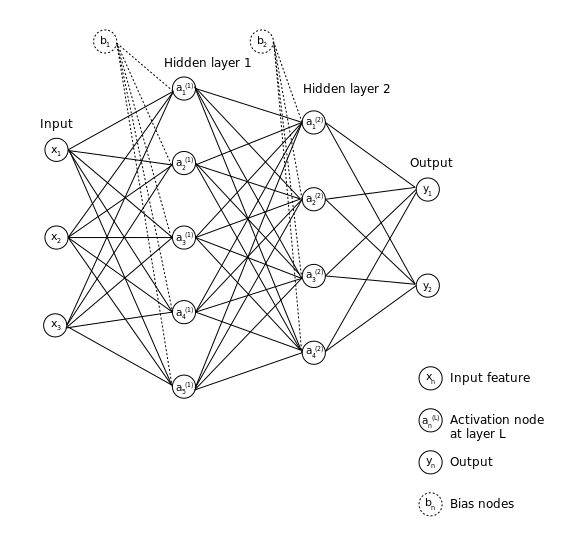

There are several flavors of neural network architectures, each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, where information flows through from X to y, and no inofmration feeds back into itself. These principles can then be applied to construct other neural network variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers - these are considered to be **deep neural networks **if there are multiple hidden layers. To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains only 1 hidden layer.

## Training a neural network using forward propagation

The training phase of a neural network is called **forward propagation**, and consists of iteratively performing a linear transformation and non-linear transformation until we reach the output layer.

### Linear transformation 

Let's consider our artificial dataset, which consists of 50 observations and 6 features. 

**The first step in training a neural network is to perform a linear transformation of the data**, similar to what you've seen in the linear regression part of the course, to compute a new "feature". Because we only have 1 node, The formulation for the 6 features is the following equation:


$$\begin{array}{l}
z_1 ={1\cdot x}_1 +b\\
z_2 ={0\cdot x}_2 +b\\
\vdots \\
z_6 ={0\cdot x}_6 +b
\end{array}$$
 

The vectorized form of these equations can be written as:


$$Z=X^T w+b$$


$X$ has the features spanning the columns, and the observations span the rows. This is the same form as the linear regression problem. And just like our regression problem, we're learning two parameters: the **weights** ($w$) and the **bias** ($b$) values. 

Let's now compute how the two parameters $w$ and $b$ impact the solution $Z$, and then plot the relationship between `X` and `Z`:

% Initialize inputs using random numbers from default seed
rng('default');
Xtrain          = normrnd(0, 1, [50, 6]);

% Example with three different w and b vectors
wArray = [[1, 0, 0, 0,  0, 0]; ...   % One activation node
          [1, 0, 2, 0,  0, 0]; ...   % Two activation nodes
          [1, 0, 2, 0, -2, 0]];      % Three activation nodes

bArray = [zeros([50, 1]), ...        % All zeros
          randn([50, 1]), ...        % Random values
          ones( [50, 1])];           % All ones

% Construct several values for Z by changing the weights and bias
% parameters
for i = 1:size(wArray, 1)
    for j = 1:size(bArray, 2)
        b       = bArray(:, j);
        w       = wArray(i, :);
        Z{i, j} = Xtrain * w' + b;
    end
end

plotLSLines(Xtrain, Z);

From left to right, the biases are changing from all zeros, to random, to all ones. From top to bottom, the number of weights in the model vary from 1 to 3. As you can see, the weights act like the $\beta$ coefficients estimated in linear regression

### Non-linear transformations using an activation function

**The second step involves transforming the data again using a non-linear function.** In this particular example, let's the sigmoid function. 

To review, data can be transformed to the characteristic 'S' curve using the following equation:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


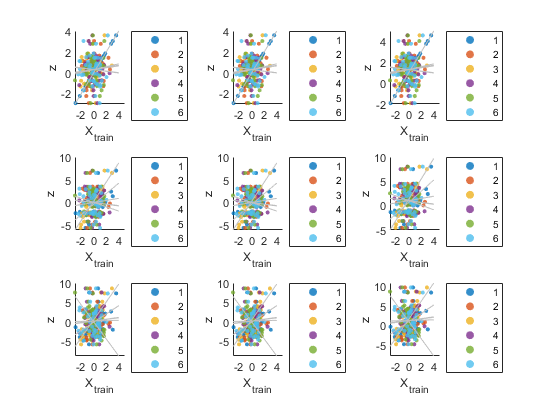

plotSigmoidFunction()

This function is useful for classification, especially if we're trying to predict two possible outcomes (a binary classification problem). This is due to the base `e` term in the denominator, which will either make the value `A` approach 0 if $z_i$ is large, or 1 if$z_i$ was small.

To implement the sigmoid function in MATLAB, we can use the `activationFnc` function provided in the project folder. Shown below are the relevant parts of the function used to transform the data using a sigmoidal function:

Let's now transform our `Z` array using the sigmoid function and see the results of the transformation:

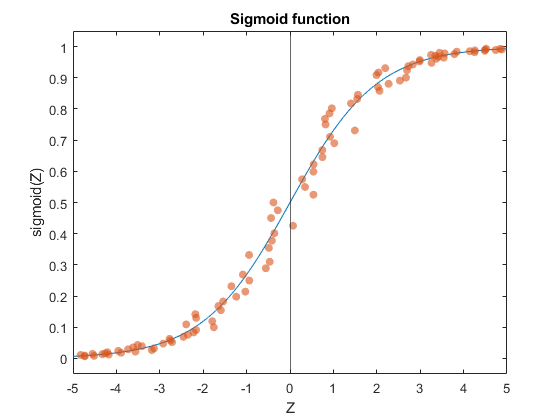

% Compute A using the Z cell array
for i = 1:size(Z, 1)

    for j = 1:size(Z, 2)
        A{i, j} = activationFnc(Z{i, j}, 'Sigmoid');
    end
end
plotSigmoidFunction(Xtrain, A);

From left to right, the biases are changing from all zeros, to random, to all ones. From top to bottom, the number of weights in the model vary from 1 to 3. As we add more weights, the features tend to become more complex. However, a clearer decision boundary starts to form - values are now starting to either converge to either 0 or 1, which is the goal of classification. 

### A full round of forward propagation

Let's now put all of these concepts together to run a full round of forward propagation using breast cancer datasets built into MATLAB. 

The dataset can be called using `load cancer_dataset` and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

To save space in the code blocks, an accessory function `loadCancerData` has been made to load the dataset preprocessed as a training and test set. This function does the following steps:

- Loads the dataset

- Splits into training and test datasets

- Standardize the inputs

clear all;
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

Brace indexing is not supported for variables of this type.

To keep the network relatively simple, we'll use 10 activation nodes. Additionally, we'll randomly choose values for `w` and `b. L`ater we'll discuss why this random initialization is important for both the weights and the biases.

rng('default');
% Weights and biases for input -> hidden
w1 = randn([size(Xtrain, 2), 10]) * 0.01;
b1 = randn([size(Xtrain, 1), 1])  * 0.01;

Let's now run forward propagation, first from the input layer to the hidden layer:

% Run forward propagation for input -> hidden
actFnc = 'Sigmoid';
Z1     = Xtrain * w1 + b1;
A1     = activationFnc(Z1, actFnc);

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round. Additionally, we will not bias our answers in this layer.

% Weights for hidden -> output
w2 = rand(10, 1) * 0.01;

% Run forward propagation for hidden -> output
Z2 = A1 * w2;
A2 = activationFnc(Z2, actFnc);

% Since we've made our way to the output layer, A2 is our final predicted y
% value
ypred = A2;

That's a full round of forward propagation! Now we need to now see how well our model performed using a cost function.

## Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a classification problem, we can use the Cross-Entropy cost function.

### **Cross-Entropy cost function**

Because we are using logistic regression as the activation function for our classification problem, we can use the **Cross-Entropy (aka Log-Loss) cost function** to score our classifier. 


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


$m$ = number of observations, $y_{\textrm{train}}$ = the response variable, and $y_{\textrm{pred}}$ = the predicted value for$y_{\textrm{train}}$ from forward propagation. The **cost** value can be computed using the code from the `costFunction`. 

J = costFunction(Ytrain, ypred, 'Log-Loss');

## Optimizing neural network parameters using backward propagation

After computing the cost, we need to optimize the model parameters (`w` and `b)` until the error is below a given threshold or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called **gradient descent, **where we're adjusting the model parameters by following the gradient that minimizes the model error. In our case, we need to **back propagate** and compute the gradients **dW** and **db** using the variables we computed in forward propagation. 

### Optimizing parameters `W` and `b` using gradient descent

The objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \textrm{db}\right)
\end{array}$$
 

where $\alpha$ is the learning rate hyperparameter, which is a constant value that controls how fast we move along the gradient.  

### Finding dW and db using back propagation

To compute the gradient `dW` and `db`, we need to see which weights and biases contribute the highest cost. Starting from the output layer to the input layer and compute the gradient - that is, how should the `w` be increased or decreased to reduce the cost.

We can set this up as two differential equations to get the gradient:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

And ideally, we would work these chains of differential equations out for each layer, and each component of the neural network we computed. After working out the differential equations, we get the following set of derivatives that are needed to compute `dW2`, `dW1`, and `db1.`

**Back propagating from the output layer to the hidden layer:**


$$\begin{array}{l}
\textrm{dZ2}=-\left(\frac{y_{\textrm{train}} }{y_{\textrm{pred}} }-\frac{1-y_{\textrm{train}} }{1-y_{\textrm{pred}} }\right)\\
d\textrm{W2}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\cdot \textrm{A2}\right)
\end{array}$$


**Backpropagating from the hidden layer to the input layer:**


$$\begin{array}{l}
\textrm{dZ1}=\textrm{W2}\cdot \textrm{dZ2}\cdot g^{\prime } \left(\textrm{Z1}\right)\\
d\textrm{W1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\cdot \textrm{A1}\right)\\
\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)
\end{array}$$


The derivative of the sigmoid function is 

$g^{\prime } \left(\textrm{Z1}\right)\;=\;\textrm{sigmoid}\left(\textrm{Z1}\right)\cdot \left(1-\textrm{sigmoid}\left(\textrm{Z1}\right)\right)$. 

This is equivalent to 


$$g^{\prime } \left(\textrm{Z1}\right)\;=\;\left(1-{\textrm{A1}}^2 \right)$$


### A full round of back propagation

Now let's codify the expressions above to run a full round of back propagation. First we need to initialize constants that will be used in back propgation. A good starting point for the learning rate is 0.05. 

% Initialize constants that will be used in the following expressions
alpha = 0.05;
m = size(Xtrain, 1);

First let's back propagate from the output layer to the hidden layer:

% Back propagation from output layer back to hidden layer
dZ2 = Ytrain ./ ypred - ((1 - Ytrain) ./ (1 - ypred));
dW2 = (1/m) .* (A1' * dZ2);

Next let's back propagate from the hidden layer to the input layer:

% Back propagation from hidden layer to the input layer
dZ1  = (dZ2 * w2') * (1 - A1.^2)';
dW1  = sum((1/m) .* dZ1' * Xtrain);
db1  = (1/m) .* sum(dZ1, 2);

And finally, let's update the values using gradient descent:

% Update w2, w1, and b1 using the gradients we just computed
w2 = w2 - (alpha .* dW2);
w1 = w1 - (alpha .* dW1');
b1 = b1 - (alpha .* db1);

We have successfully back propagated to get better values for `W` and `b. `To train the neural network even more, we would iterate the entire process of forward propagation, computing the cost, and backward propagation several times until we reach the minimum cost value. 

## Running the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. Each iteraction where we run a single round of forward and backward propagation is called an **epoch. **This is another hyperparameter that we can tune to assess model performance. 

The `SNN` function for the shallow neural network is modularized to the three steps we performed: forward propagation, evaluating the cost, and back propagation. The values from forward propagation are stored in a `structure` data type called `cache. `Similarly, the values from back prop are stored in the `backwardCache` variable. Further documentation is included in the `SNN` function. 

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

clear all;
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

% Initialize other important model parameters 
numOfActiveNodes = 10;
alpha = 0.2;
epoch = 1000;
actFnc = 'Sigmoid';
randomstate = true;

% Run the neural network
model = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, actFnc, randomstate);

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

% Plot of the cost:
plot(1:length(model.J), model.J);
title(strcat('Cost with \alpha = ', string(alpha)));
xlabel('Number of iterations');
ylabel('Cost (J)');

As you can see, while it appears that the model is approaching a minimum cost value, it looks like there is still room for improvement as we have not reached the global minimum. Later on, we'll optimize the model hyperparameters as well to get the best shallow neural network model.

### Assessing model accuracy

#### Hold out accuracy

Next, let's use the test set to come up with a prediction. To do that using our neural network, we can use the following function from the `predict` script:

ypred = predict(model, Xtest, Ytest, 'SNN');

Now that we have a prediction from our neural network, we can evaluate the model accuracy. To do that, we need to transform the `ypred` field in the model to be either 0 or 1. For the decision boundary, let's use 0.5: if the value is greater than or equal to 0.5, we'll assign that index to 1, otherwise it's 0. We'll also plot the confusion matrix and report the hold out accuracy.

summary = plotConfusionMatrix(Ytest, ypred);

The average accuracy across all classes is 79.55%, which is a decent score for a single hold out. Additionally, the accuracy for predicting cancer (70.83%) and healthy (90.00%) is pretty good as well.

#### Cross validation accuracy

Of course, the hold out accuracy itself is not necessarily the best measure to evaluate the neural network. Let's also run 10-fold cross validation and see how our model does on average. The `crossValidate` function is used to compute k-fold cross validation with two classes 

kfold = 10;
Summary = crossValidate(Xtrain, Ytrain, model, kfold);

The average accuracy across all classes is 81.45%, which is pretty good considering we did not even pursue further optimization of the hyperparameters yet. Additionally, the accuracy for predicting cancer (72.24%) and healthy (93.68%) is pretty high.

## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, there are issues with training them. We'll discuss some of these issues in this section.

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 3 alternative cases: if w and b are all zeros, all ones, and large random numbers.

#### Setting w and b to be all zeros

We'll go back to our synthetic dataset with 50 observations and 6 features and plot the results when w and b are all zero.

% Initialize inputs using random numbers from default seed
rng('default');
Xtrain = normrnd(0, 1, [50, 6]);

% Example with three different w and b vectors
w = [0, 0, 0, 0, 0, 0];
b = zeros([50, 1]);
Z = Xtrain * w' + b;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid'));

If the values are all zeros, the neural network stops learning the features - they will be stuck at a value for Z and 0.5 for A during every iteration.

#### Setting w and b to be all ones

Let's see what happens when we set w and b to be all ones:

% Example with three different w and b vectors
w = [1, 1, 1, 1, 1, 1];
b = ones([50, 1]);
Z = Xtrain * w' + b;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid'));

As you can see, our features end up being transformed to log-odds by the activation function. Thus, the neural network algorithm becomes a logistic regression classifier when using the sigmoid activation function.

Setting w and b to be large random numbers

Finally, let's complete this exercise by seeing what happens when the random values are large.

% Example with three different w and b vectors
w = randn([1, 6])*10;
b = randn([50, 1])*10;
Z = Xtrain * w' + b;
plot(activationFnc(Z, 'Sigmoid'));

Values start to converge to either 0 or 1 really fast, but this can simply be biased by the random number generated. Thus, large numbers are also a terrible way to initialize these values.

#### Symmetry breaking

Symmetry breaking is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning and we allow the neural network to approach a better solution through back propagation / gradient descent. 

### Overfitting

Recall that our objective in machine learning is to build a model that balances the model's ability to minimize bias and variance. Neural networks are relatively complex models, and are susceptible to model overfitting - that is, they are susceptible to learning from noisy data. This is especially true when the number of predictors `p` is much greater than the number of observations `n`. 

To address this issue, regularization is usually imposed in the loss function to select the predictors that best explain the variance of the dataset. Thus, we reduce the amount of noise in the dataset, allowing the neural network to better capture the trends in the data. 

### Data scaling

It is good practice to standardize all the features to have a mean of zero and standard deviation of one. This ensures that the inputs are treated equally by the random starting weights.

### Multiple cost minima

The error function may not be convex -  in other words, there may be multiple minima that gradient descent can converge to. To try to get the best solution, different learning rates should be explored.

## Benchmarking against a logistic regression classifier

A neural network is a more flexible model compared to other models, in that it performs both linear and nonlinear transformations on the data. Let's see how well our shall model performs against a logistic regression classifier, a less flexible model that only performs nonlinear transformations on the dataset.  

### Logistic regression

Recall that the formulation for a logistic regression problem is 1) applying the sigmoid function to our linear equation $Z=X^T \beta$ to transform the values to log-odds, then 2) finding the value of $\beta$ using the maximum likelihood objective function. Thus the equation we're trying to solve for a logistic regression problem is:


$$y=\frac{1}{1+e^{-X^T \beta } }$$


Let's load up the dataset again:

clear all;
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

Now let's set some of the other hyperparameters similar to the shallow neural network. 

% Initialize other important model parameters 
alpha = 0.2;
actFnc = 'Sigmoid';
randomstate = true;
epoch = 1000; 
m = size(Xtrain, 2);
theta = randn([size(Xtrain, 2), 1]) * 0.01;
b = randn([size(Xtrain, 1), 1]);

To set the coefficients `Beta` and `b`, we'll use the same method we used for the shallow neural network:

logistic = logRegress(Xtrain, Ytrain, ...
    theta, b, alpha, epoch);

If you're interested in the implementation of this logistic regressor, you can check out the `logRegress` function.

Let's feed the model into the `predict` function to get the hold out values:

ypred = predict(logistic, Xtest, Ytest, 'Logistic');
logisticCM = plotConfusionMatrix(Ytest, ypred);

#### Shallow neural network

Let's re-train our neural network and compare the two results

% Train model
clearvars -except Xtrain Ytrain Xtest Ytest ...
    alpha actFnc randomstate epoch m logSummary

numOfActiveNodes = 10;
NeuralNetwork = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, actFnc, randomstate);
ypred = predict(NeuralNetwork, Xtest, Ytest, 'SNN');
NNCM = plotConfusionMatrix(Ytest, ypred);

#### Results

As you can clearly see from comparing both the neural network and the logistic regression classifiers, the neural network has better generalizability, and outperforms the logistic regression model. 

However, because the neural network almost operates as a "black box" due to the transformations that occur in forward prop, it is also a lot less interpretable. 

## Tuning neural network model components

### Alternative Activation functions

#### Rectified Linear Units (ReLU) Activation Function

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. In back propagation, the gradient becomes really small, resulting in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to learning model parameters.

- Further, our values are between 0 and 1. Because the values are not zero-centered, our algorithm becomes more difficult to optimize.

Thus, the formulation of the ReLU is as follows:


$$\begin{array}{l}
\textrm{ReLU}\left(Z\right)=\max \left(0,\;Z\right),\\
\textrm{where}\;A=\left\lbrace \begin{array}{cc}
\max \left(Z\right) & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
0 & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.
\end{array}$$


And the function has the following distribution:

plotReLU();

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- All of the negative values have a derivative value of 0, while for positive values, the derivative is 1. Thus, this rectifies the vanishing gradient problem.

- It is also computationally economical, and easy to optimize.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

To implement the ReLU using MATLAB, we can use the `activationFnc` function, using `ReLU` as the second argument. The ReLU is not a magic bullet, and there are limitations to it, despite it being a better activation function than other alternatives. Specifically, for values of Z < 0, the gradient will be 0 because the weights will not get adjusted during gradient descent. Thus, these neurons will not respond to back propagation. This is known as the **dying ReLU problem**.

#### Leaky ReLU Activation Function

To counteract the dying ReLU problem, the following solution has been proposed: instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus prevents the information loss from the ReLU.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution:

plotLeakyReLU();

To implement the Leaky ReLU using MATLAB, we can use the `activationFnc` function, using `Leaky` `ReLU` as the second argument. Additionally, we can specify the scaling factor $\varepsilon$ as the third argument. The default value for $\varepsilon$ is 0.01:

#### Benchmarking different activation functions

Finally, let's compare three neural networks that use all three different activation functions, and see which one performs the best:

% Train the 3 models
logisticAF  = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'Sigmoid', randomstate);
ReLUAF      = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'ReLU', randomstate);
LeakyReLUAF = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'Leaky ReLU', randomstate);

% Plot the cost curves:
figure;
plot(1:length(model1.J), model1.J); hold on;
plot(1:length(model2.J), model2.J); hold on;
plot(1:length(model3.J), model3.J); hold on;
title('Cost with \alpha = 0.05');
xlabel('Number of iterations');
ylabel('Cost (J)');

## Summary

We have covered how neural networks work under the hood, and coded a shallow neural network from scratch. We also saw how modifying various parameters and hyperparameters influence the model prediction. Finally, we applied the model to a breast cancer dataset to predict whether an patient has benign or malignant tumor. 

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence.